clear

%%%%%%%%%%%% Constants %%%%%%%%%%%%%%%%%%%%%

% Environment
g = 9.81

g = 9.8100

r_E = 6378137 % Earth radius

r_E = 6378137

P_0 = 101325 % Base pressure Pa

P_0 = 101325

L_b = 0.0098 % Temp change K/m

L_b = 0.0098

T_b = 293.15 % Base temp K

T_b = 293.1500

Baro_exp = (-g*0.02897)/(8.3145*L_b)

Baro_exp = -3.4878


h_0 = 0 % Launch pad height

h_0 = 0


% Rocket parameters
A_rocket = pi*0.15^2

A_rocket = 0.0707

S_e = pi*0.02^2

S_e = 0.0013

I_s = 250 % Specific impulse

I_s = 250

T_max = 1000

T_max = 1000

T_min = 500

T_min = 500

Ang_max = deg2rad(10) % Max thrust vector angle

Ang_max = 0.1745

Vec_max = T_max*sin(Ang_max) % Max thrust vector force

Vec_max = 173.6482

Tilt_max = deg2rad(20) % Max safe rocket tilt

Tilt_max = 0.3491


t_P2 = 1 % Primary thruster 2% settling time

t_P2 = 1

sigma = 4/t_P2

sigma = 4

t_P = 1/sigma % Primary thruster time constant

t_P = 0.2500

t_S = 0.1 % Secondary thruster time constant

t_S = 0.1000

t_V = 0.1 % Vectoring actuation time constant

t_V = 0.1000


r_S = 0.15 % Moment arm to secondary thrusters

r_S = 0.1500

T_max_s = 1

T_max_s = 1


ang_safe = deg2rad(20)

ang_safe = 0.3491

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%% Initial conditions %%%%%%%%%%%%
N = 0;
E = 0;
D = 0;

U = 0;
V = 0;
W = 0;

P = 0;
Q = 0;
R = 0;

Phi = deg2rad(0);
Theta = deg2rad(0);
Psi = deg2rad(0);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

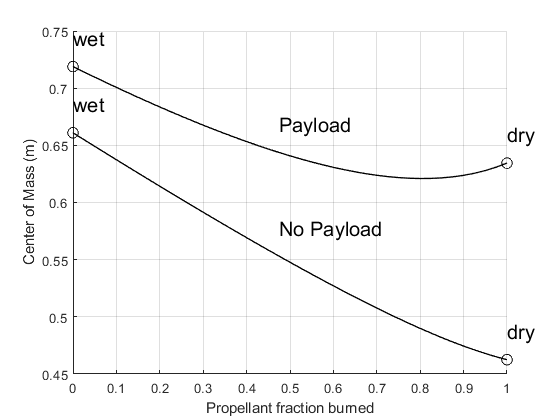

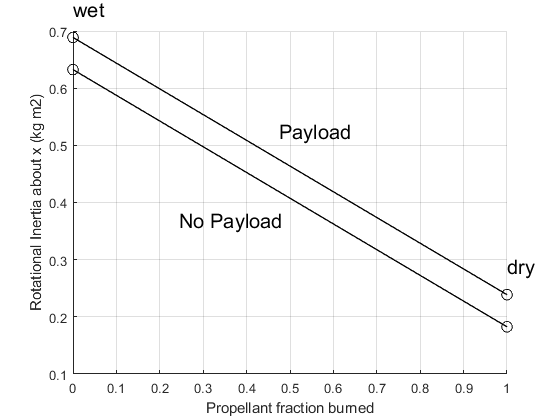

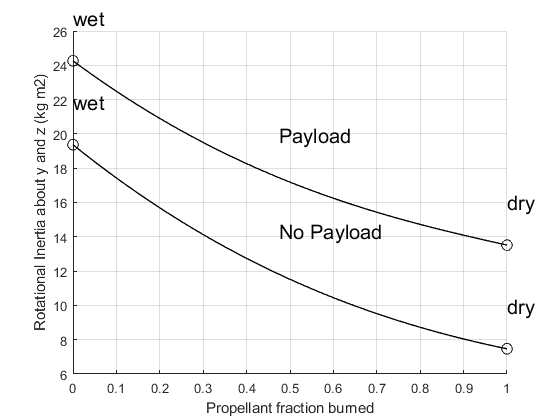

% Rocket paramaters
parameter_vary

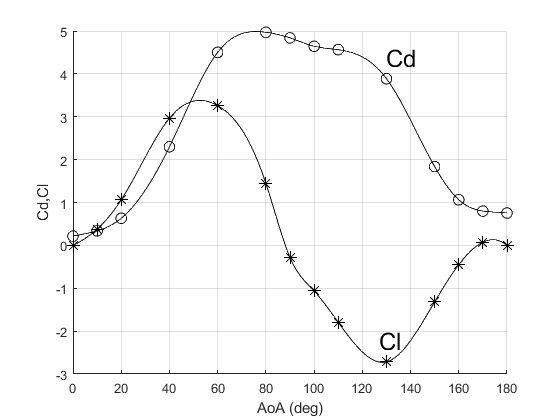

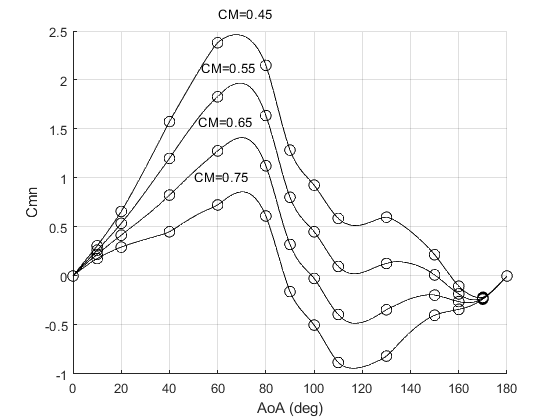

Ct_rot = -1.1887

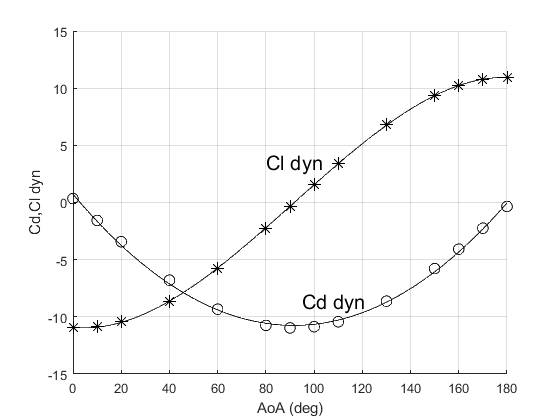

drag_wave_lookup2 = 0.7148

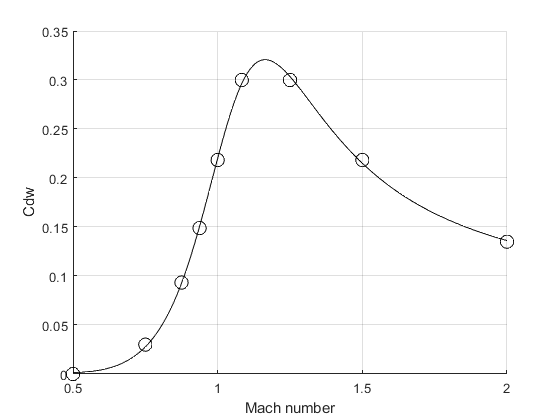

coeff_calc

% Controllers
roll_control

Roll is controllable


wn = 5.6577

k_roll =    -0.1528   13.7471


wn = 1.3333

Ts_climb = 0.0375

p_s_want =    -1.3333
   -1.3333


p_z_want =     0.9973
    0.9973


Climb is controllable

C_climb =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 88.1, Ki = 23.9, Ts = 0.002
 
Sample time: 0.002 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.3327
           PhaseMargin: 60.0000


Alt is controllable

C_alt =
 
  Kp = -0.427
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.5000
           PhaseMargin: 72.1255


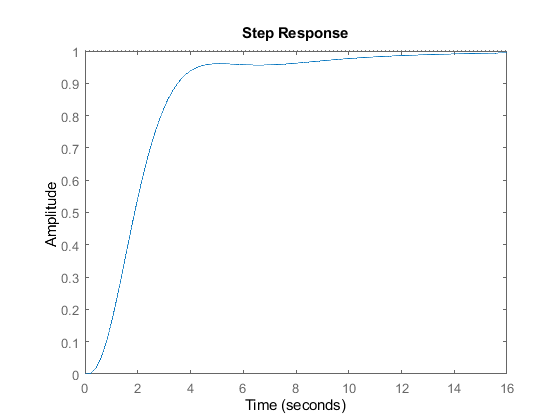

heave_control

sysC =
 
  A = 
            x1       x2       x3       x4       x5
   x1      -10        0        0        0        0
   x2  0.03872        0        0        0        0
   x3        0        1        0        0        0
   x4        0        0        0        0        1
   x5        0        0    15.62        0        0
 
  B = 
       u1
   x1  10
   x2   0
   x3   0
   x4   0
   x5   0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



pls =      0
   -10
     0
     0
     0


zers =      0
     0
     0


C_rate =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 77.7, Ki = 51.6, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 2.9486
           PhaseMargin: 60.0000


sysC =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1      -10     -777        0        0        0    515.7
   x2  0.03872        0        0        0        0        0
   x3        0        1        0        0        0        0
   x4        0        0        0        0        1        0
   x5        0        0    15.62        0        0        0
   x6        0       -1        0        0        0        0
 
  B = 
        u1
   x1  777
   x2    0
   x3    0
   x4    0
   x5    0
   x6    1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



pls =    0.0000 + 0.0000i
  -4.5408 + 1.0620i
  -4.5408 - 1.0620i
  -0.9183 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


zers =    -0.6638
         0
         0


C_ang =
 
  Kp = 1.35
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5887
           PhaseMargin: 60.0041


S = struct with fields:
        RiseTime: 77.5893
    SettlingTime: 373.2070
     SettlingMin: 0.9029
     SettlingMax: 1.0676
       Overshoot: 6.9518
      Undershoot: 0
            Peak: 1.0676
        PeakTime: 163


sysC =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1         -10        -777  -6.037e+04           0           0       515.7
   x2     0.03872           0           0           0           0           0
   x3           0           1           0           0           0           0
   x4           0           0           0           0           1           0
   x5           0           0       15.62           0           0           0
   x6           0          -1       -77.7           0           0           0
 
  B = 
           u1
   x1   60.37
   x2       0
   x3       0
   x4       0
   x5       0
   x6  0.0777
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



pls =    0.0000 + 0.0000i
 -16.4951 + 0.0000i
   3.5788 +11.3648i
   3.5788 -11.3648i
  -0.6626 + 0.0000i
   0.0000 + 0.0000i


zers =    -0.6638
         0


C_vel =
 
  Kp = 2.3e+03
 
P-only controller.



info = struct with fields:
                Stable: 0
    CrossoverFrequency: 17.3459
           PhaseMargin: NaN


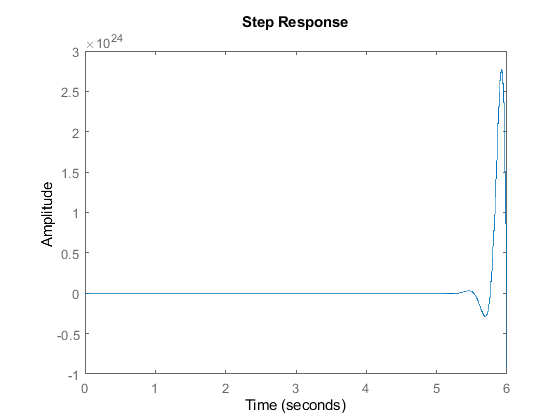

horizontal_control